# Test Case - Motor Generator 2

mdl = "MotorGenerator2_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorGenerator2_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Road grade", Time="2");
simIn = setBlockParameter(simIn, mdl+"/Road grade", After="0");

simIn = setBlockParameter(simIn, mdl+"/Brake force", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Brake force", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Brake force", After="0");

simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.MG2_Temperature_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "1000");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

## Visualize Simulation Result

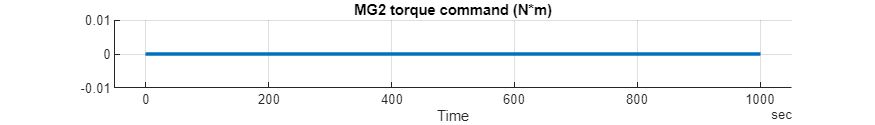

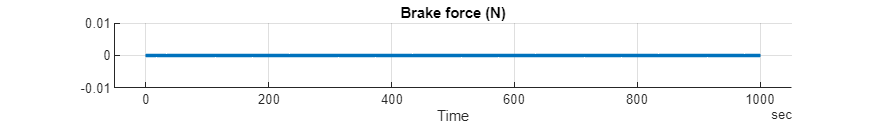

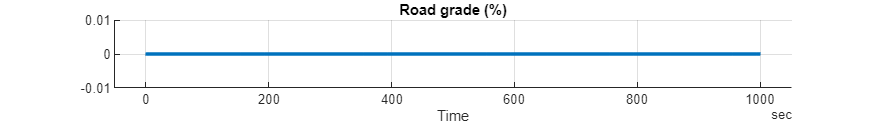

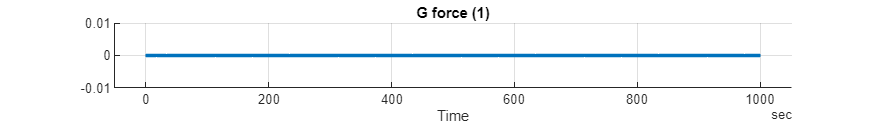

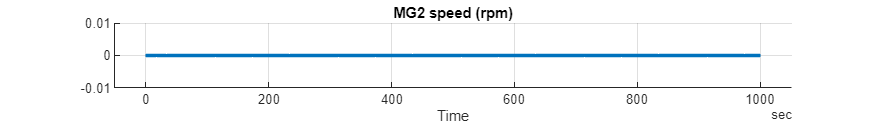

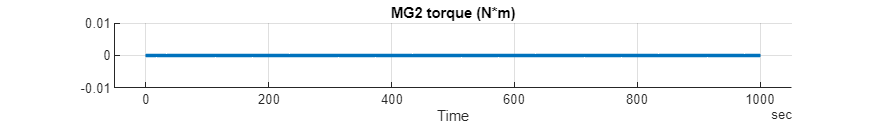

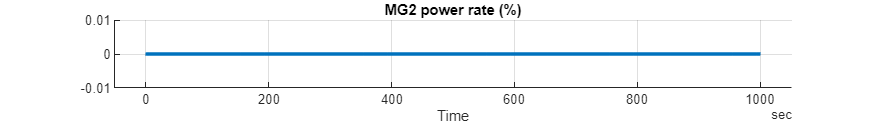

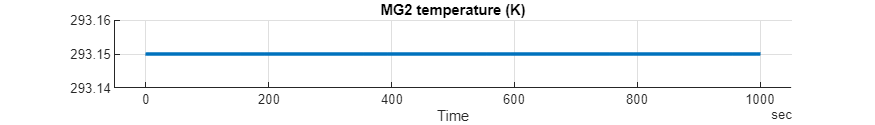

simData = extractTimetable(simOut.logsout);

MotorGenerator2_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*